# Three-Phase Photovoltaic (PV) System

## **Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Introduction

A three phase solar grid system is a critical component in any solar system where the DC power harnessed from the solar panels is turned into AC power with a three-phase output, so it can be smoothly transmitted over long distances and used by all consumers residing at different distances from the solar panels.

A three-phase inverter adjusts the generated solar power to match the frequency and phase, ensuring stable and seamless integration. The variability of available solar energy is managed through control techniques like a proportional integral (PI) controller and maximum power point tracking (MPPT) algorithms, enabling the inverter to respond to irradiance and temperature changes, and stabilizing the grid to prevent voltage drops and unwanted noise. 

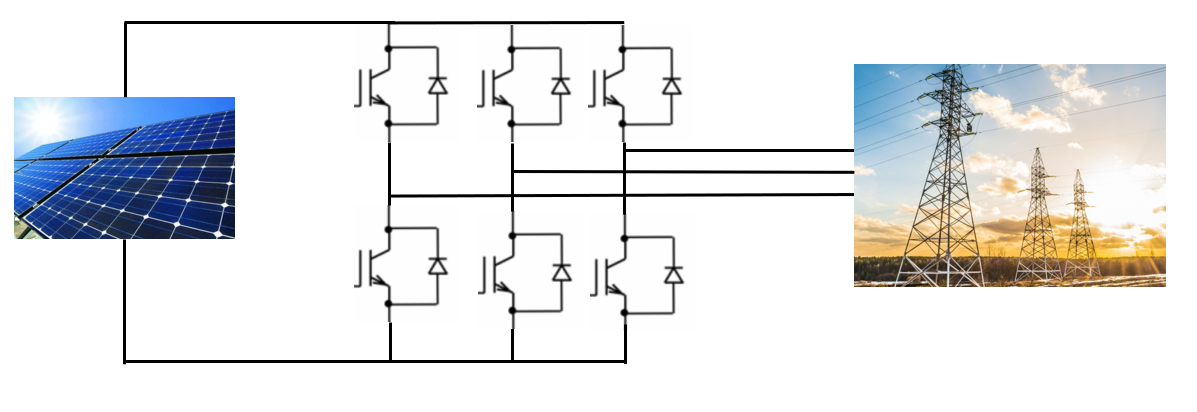

The structure of the three-phase PV system 

## Circuit

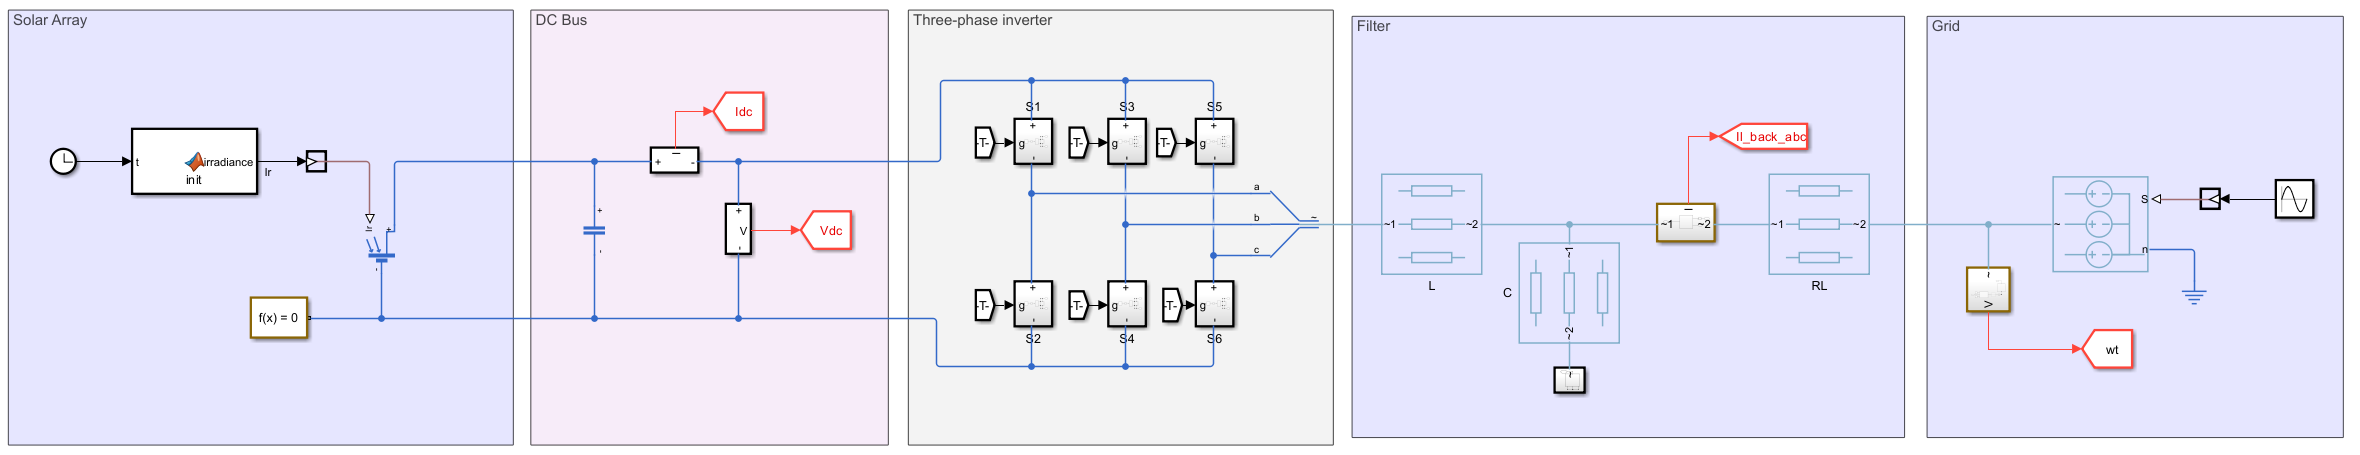The circuit above shows the solar array connected to the power grid through a three-phase inverter and a filter. 

Click the button below to learn more about different sections of the model: 

selection1 = "No Selection";
switchRectifier(selection1);

### Solar Panel

Photovoltaic (PV) technology is a transformative approach to generating electricity that harnesses sun power through solar panels made of semiconductor materials. This technology is pivotal in the move towards sustainable energy solutions because it provides a clean, renewable source of energy that significantly reduces greenhouse gas emissions compared to traditional fossil fuels.

Here is a picture of the PV module in the real world:

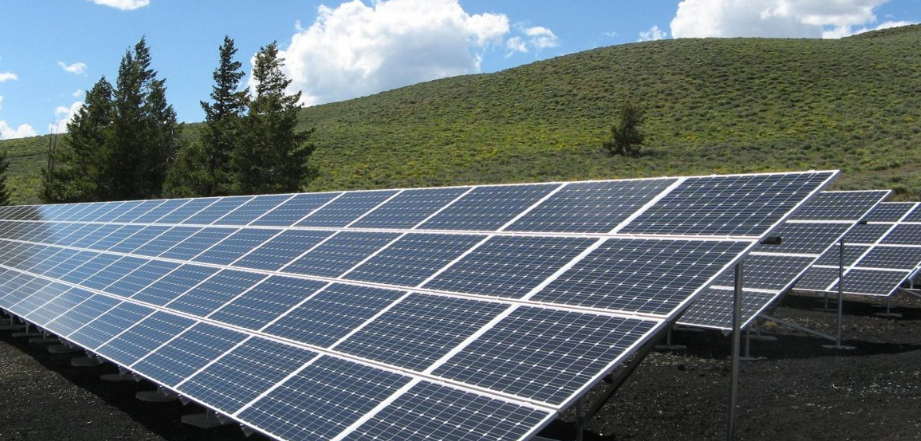

**Current-voltage **curves illustrate the relationship between current and voltage under proper irradiance and temperature conditions (normally defined as 1000 $w/m^2$ and 25 degrees Celsius, respectively).

The following simulink model shows the detailed structure of the PV model:

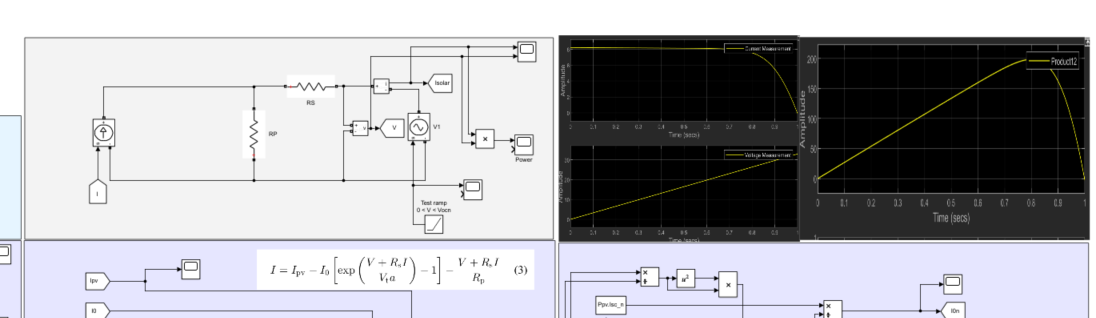

Click below to further explore this model.

 
open_system("model/PVmodule.slx")

Now you can use the following sliders to adjust the irradiance and temperature conditions of the PV cell. See how these changes impact the **current-voltage** and **voltage-power** curves.

Irradiance=739;
Temperature=59;
 
pv_curves(Irradiance, Temperature);

### Three-Phase PV Circuit Simulation

Let's turn our attention back to the full PV circuit.

Click the **Open & Run** button below and explore the model.

After the simulation is complete **(allow a few minutes)**, you will get the following four plots:

- DC Bus Voltage

- Inverter Output Current 

- Output Active Power

- MPPT Voltage (Vmppt)

run('Script\Initialization_PV.m')
open_system('model\three_phase_solar_grid_SSC.slx')
warning('off','all')
simOut = sim('three_phase_solar_grid_SSC.slx', 'ReturnWorkspaceOutputs', 'on');
runmodel_threephase(simOut);

### Three-Phase Inverter

A three-phase inverter is a crucial component in power electronics, widely used to convert** direct current** (DC) into **alternating current** (AC) across three distinct phases. This type of inverter is fundamental in applications where three-phase AC power is required, such as in grid-tied solar power systems, industrial motor drives, and variable frequency drives in HVAC systems. The following schematic shows the typical configuration and workflow of a three-phase inverter.

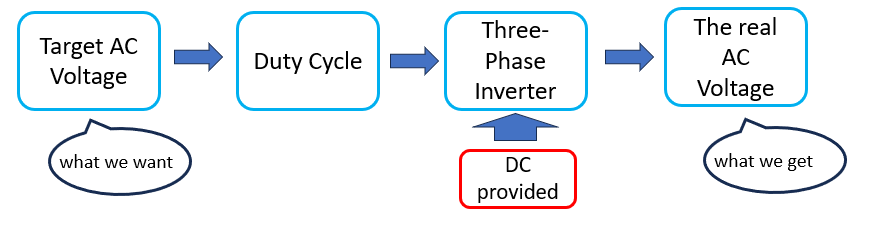

### Grid Connection

For simulation purposes, to ensure the **stability** and **quality** of the power grid, the only requirement for the inverter’s AC output is that its **frequency **matches the grid’s frequency and **phase angle**. A Phase-Locked Loop (PLL) strategy is used to measure grid frequency. At this stage, we do not need to examine the internal principles or operation of the PLL.

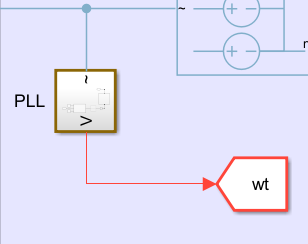

## Control Algorithm

Generally, the control algorithm includes** two** parts: **maximum power point tracking** (MPPT) and **inverter control. **

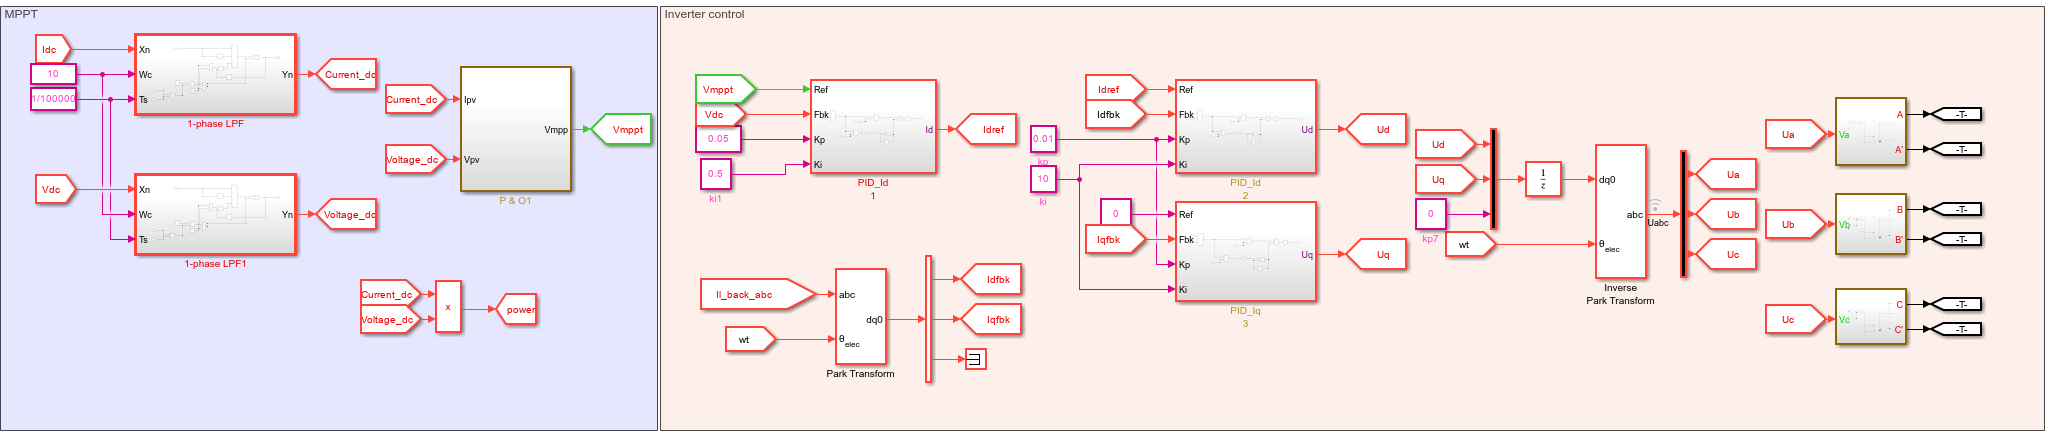

### Maximum Power Point Tracking (MPPT)

**MPPT Control** is a technique commonly used in renewable energy systems, particularly in photovoltaic (PV) solar systems, to optimize the power output from solar panels. Solar panels have a nonlinear relationship between current and voltage, and if we observe the power-voltage curve of the solar panel, we can find that there is always a maximum power point that exists under proper irradiance and temperature conditions. This point is called the maximum power point (MPP).  

There are [two major methods](https://www.mathworks.com/discovery/mppt-algorithm.html) to determine whether the PV system us operating at the MPP: perturbation and observation (P&O) and incremental conductance method. 

MPPT("No Selection")

In this simulation model, the P&O method is used.

### Inverter Control

Inverter control includes two major parts: **current and voltage controller **and **duty cycle generation **. 

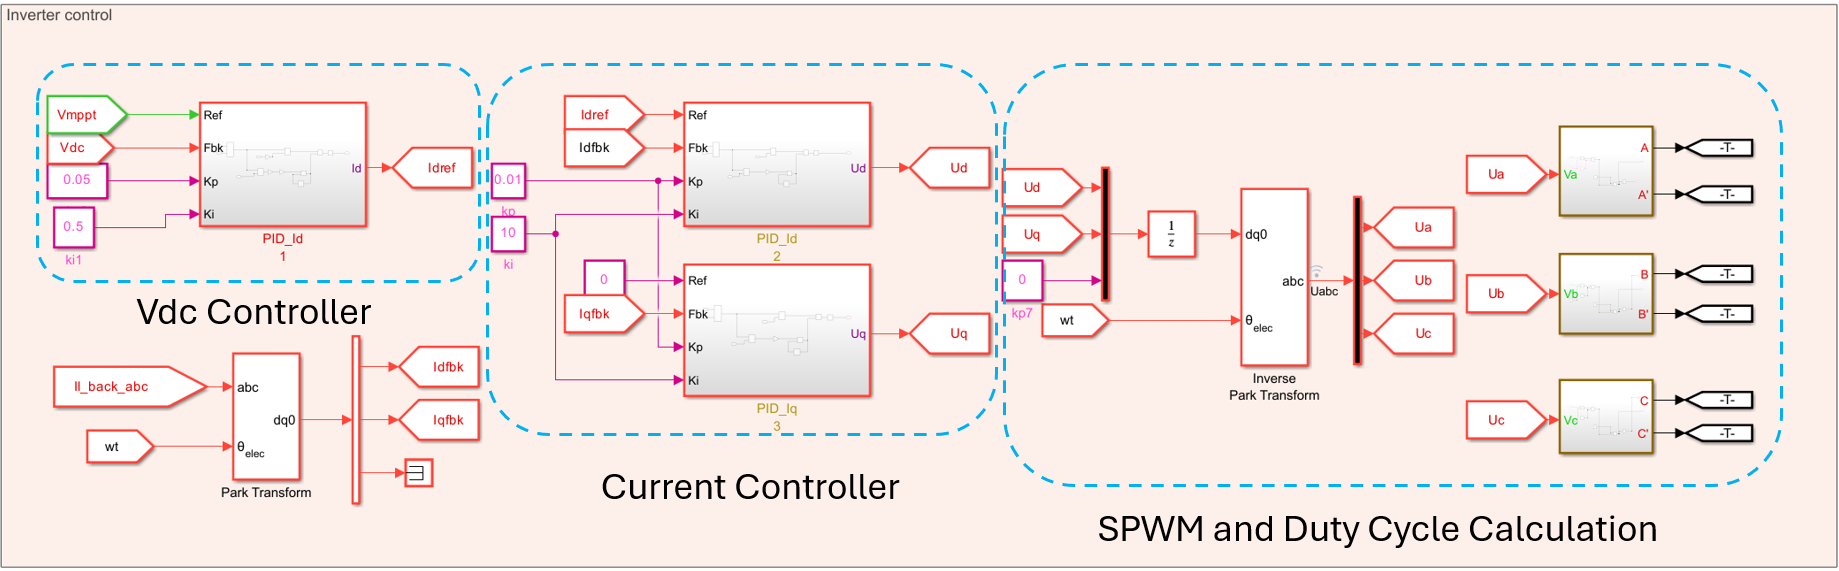

###  Reflection 

- Why do we need **current** and **voltage** controllers? Or, put another way, why do we need to control **current **and **voltage?**

- And how does the algorithm generate the duty cycle through Sinusoidal Pulse-Width Modulation?

To understand the above three controllers further, use the following drop down menu.

controller("No Selection")

## Analyzing model results

Run the three-phase solar model. Once the simulation is complete (allow a few minutes), click the scopes to explore the simulation results. 

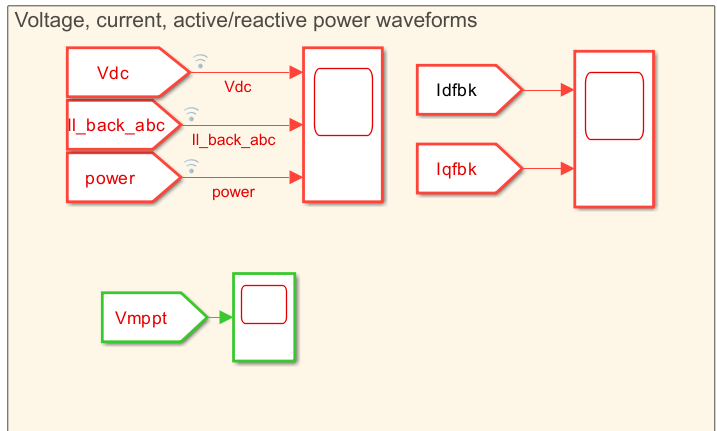

Check the following:

- Is Vdc stable at the maximum power point (MPP)?

- Is the three-phase current a smooth sine wave?

If the simulation results satisfy the above conditions, it means that Id, Iq and Vmppt are also stable. This also means the the control algorithm is doing its job!  

Select from the following menu to see reference simulation results.

result("No Selection")

## Conclusion

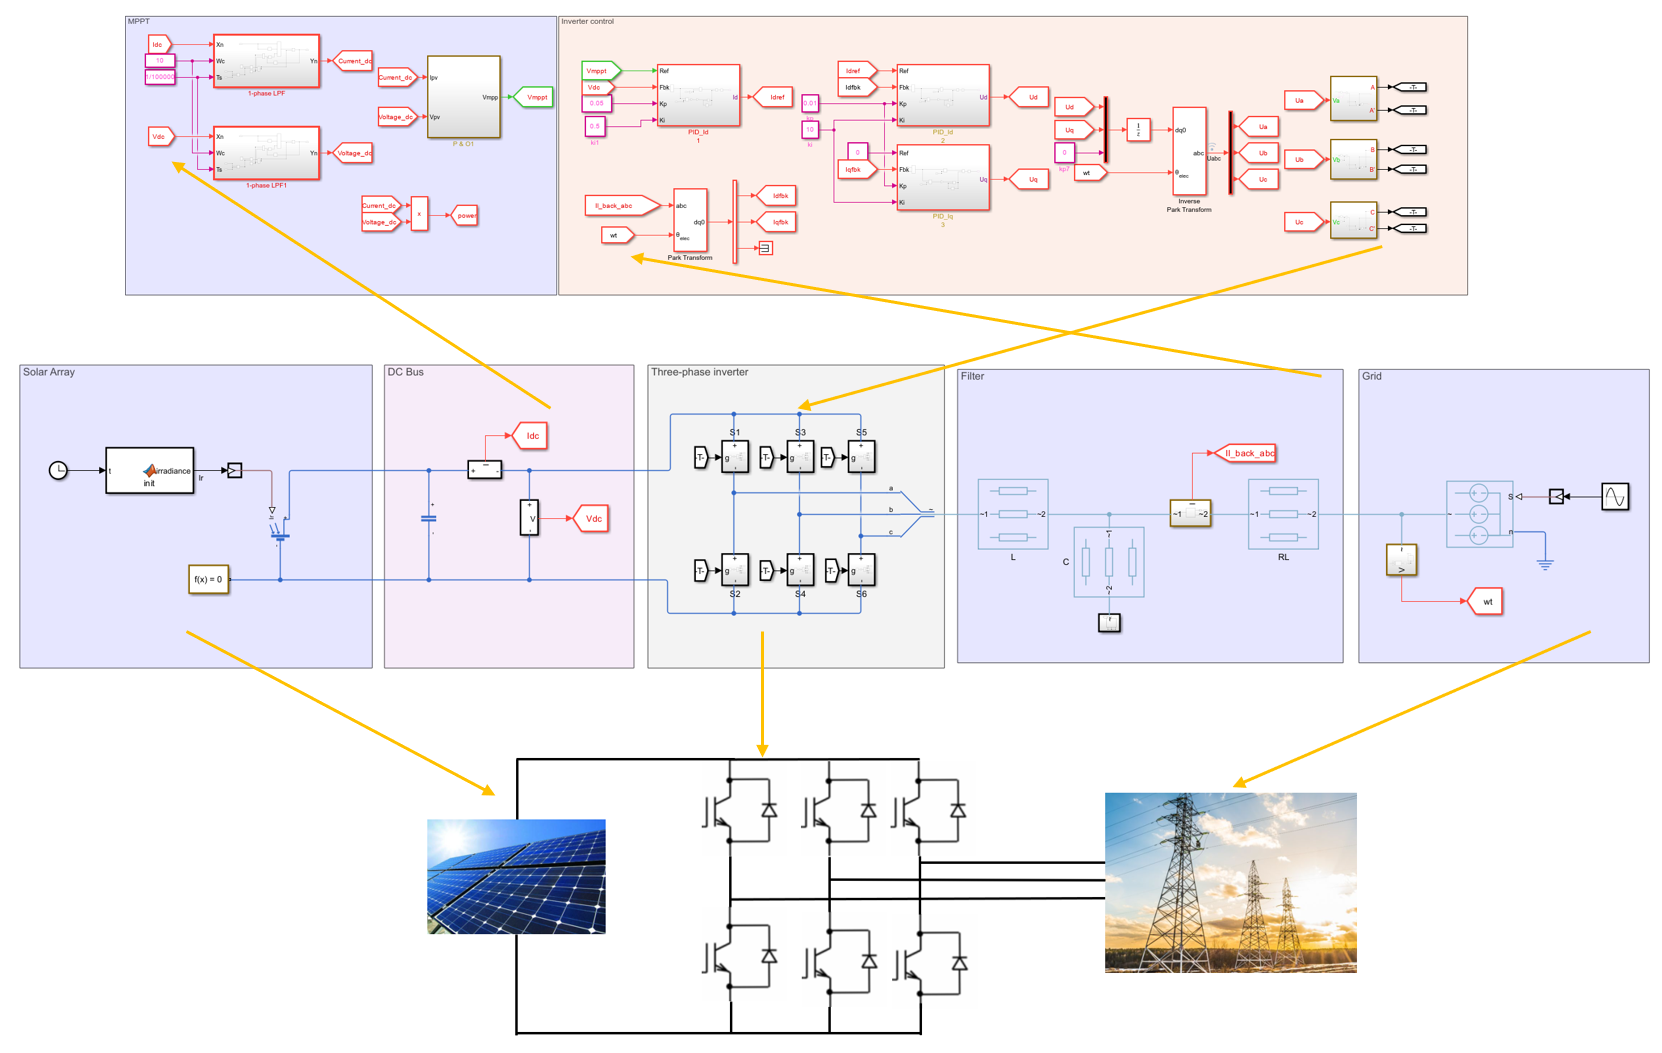

The Three-Phase PV System presented in this simulation provides a comprehensive overview of solar power generation, conversion, and integration into the electrical grid. Through the combined operation of the PV panel, MPPT controller, inverter, and grid connection, the system effectively demonstrates how renewable energy can be reliably harnessed and synchronized with utility power standards.

The MPPT algorithm ensures that the solar panels operate at their optimal power point under varying irradiance and temperature conditions. The inverter control structure, including both voltage and current control loops, maintains grid synchronization and ensures efficient power conversion from DC to three-phase AC. Simulation results confirm the system’s ability to stabilize the DC bus voltage, track MPPT reference voltage, and generate smooth sinusoidal three-phase currents.

Interactive features like irradiance and temperature sliders, waveform visualization, and model parameter tunability enhance understanding and make the model highly suitable for educational purposes. Overall, this simulation offers a practical and insightful learning experience into the design, control, and performance analysis of grid-connected PV systems.

## Exercises

 **Exercise 1. Which current in the inverter control represent the active power transmission.**

warning('on','all')
exerciseSol1(...
     false, ...
   false);
 

 **Exercise 2. In  P&O MPPT control if the current power is higher than the previous power but the current voltage is lower than previous one, what will the MPPT do with the Vmppt output.**

exerciseSol2(...
     false, ...
   false);
 

 **Exercise 3. Figure out the three-phase model, what is the switching frequency of the Mosfet? Hint: Check the duty cycle generation block.**

exerciseSol3(...
     false, ...
   false,...
   false);
 

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Solar Panel" "Three-Phase inverter" "Grid"])}
end
clf;
if opt == "No Selection"
else
   if opt == "Solar Panel"
     rect = imread("Images/PV.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "Three-Phase inverter"
        rect = imread("Images/inverter.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "Grid"
        rect = imread("Images/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    end
end
end

function MPPT(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "P&O" "Incremental Conductance"])}
end
clf;
if opt == "No Selection"
else
    if opt == "P&O"
        rect = imread("Images/PO.jpg");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Incremental Conductance"
        rect = imread("Images/IC.jpg");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Controllers" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Controllers"
        rect = imread("Images/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Circuit Part" "Control Part"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Circuit Part"
        rect = imread("Images/circuitpart.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Control Part"
        rect = imread("Images/controlpart.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end


function pv_curves(Irradiance, Temperature)
    V = linspace(0, 32.9, 100);  
    T = Temperature + 273;  
    G = Irradiance;
    k = 1.38064852e-23;
    q = 1.602176634e-19;
    Ns = 54;
    Voc_n = 32.9;
    Isc_n = 8.21;
    Rs = 0.2210;
    Rp = 415.405;
    a = 1.3;
    Eg = 1.12;
    KI = 0.0032;
    Ipv_n = 8.21;
    G_n = 1000;
    T_n = 298;
    Vt = Ns * k * T / q;
    
    I0 = calculate_saturation_current(T, T_n, Isc_n, Voc_n, Eg, a);
    Ipv = calculate_pv_current(Ipv_n, KI, (T - T_n), G, G_n);
    
 
    I_values = arrayfun(@(v) calculate_current(Ipv, I0, Rs, Rp, v, Vt, a), V);
    
  
    P = V .* I_values;
    
    figure('Position', [100, 100, 1200, 400]);  
    subplot(1, 2, 1); 
    plot(V, I_values, 'b', 'LineWidth', 2); 
    title('I-V Curve');
    xlabel('Voltage (V)');
    ylabel('Current (A)');
    grid on;
    ylim([0 10]);
 
    
    subplot(1, 2, 2);  
    plot(V, P, 'r', 'LineWidth', 2);  
    title('P-V Curve');
    xlabel('Voltage (V)');
    ylabel('Power (W)');
    grid on;
    ylim([0 220]);
   

end

function I0 = calculate_saturation_current(T, Tn, Iscn, Vocn, Eg, a)
    k = 1.38064852e-23;  
    q = 1.602176634e-19;  
  
    Vt_n = 54*k * Tn / q;  
    I0n = Iscn / (exp(Vocn / (a * Vt_n)) - 1);
    
    I0 = I0n * (Tn / T)^3 * exp(q * Eg / (a * k) * (1 / Tn - 1 / T));
end

function Ipv = calculate_pv_current(Ipv_n, KI, DeltaT, G, Gn)
    Ipv = (Ipv_n + KI * DeltaT) * (G / Gn);
end


function I = calculate_current(Ipv, Io, Rs, Rp, V, Vt, a)
    options = optimset('Display', 'off', 'TolX', 1e-6, 'TolFun', 1e-6);
    f = @(I) Ipv - Io * (exp((V + Rs * I) / (Vt * a)) - 1) - (V + Rs * I) / Rp - I;
    I = fzero(f, Ipv, options);
end

function exerciseSol1(A,B)
    
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        warning("Please select an answer!")
    elseif A && B
        warning("Please select only one answer")
    elseif A
        disp("Correct!")
    else 
        warning("Incorrect. please review the inverter control section.")
    end
end

function exerciseSol2(A,B)
    
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        warning("Please select an answer!")
    elseif A && B
        warning("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        warning("Incorrect. Please review the MPPT section.")
    end
end
function exerciseSol3(A,B,C)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        warning("Please select an answer!")
    elseif sum([A B C]) > 1 
        warning("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        warning("Incorrect. I know this is hard but try to dive deeper.")
    end
end

function runmodel_threephase(simOut)

try

    Vdc_struct         = simOut.get('Vdc');
    Il_back_abc_struct = simOut.get('Il_back_abc');
    power_struct       = simOut.get('power');
    Vmppt_struct       = simOut.get('Vmppt');

    [t1, Vdc]         = extractSignal(Vdc_struct);
    [t2, Il_back_abc] = extractSignal(Il_back_abc_struct);
    [t3, power]       = extractSignal(power_struct);
    [t4, Vmppt]       = extractSignal(Vmppt_struct);

    Vdc_plot = squeeze(Vdc);
    power_plot = squeeze(power);
    Vmppt_plot = squeeze(Vmppt);

    Il_back_abc_plot = squeeze(Il_back_abc);

    if ndims(Il_back_abc_plot) > 2
        Il_back_abc_plot = Il_back_abc_plot(:,:,1); 
        disp('⚠️ Warning: Il_back_abc was 3D. Plotting only the first "page" (Il_back_abc(:,:,1)).');
    elseif size(Il_back_abc_plot, 1) < size(Il_back_abc_plot, 2)
        Il_back_abc_plot = Il_back_abc_plot.';
    end

    figure('Name','Three-Phase PV Results','NumberTitle','off','Position',[100,100,1200,800]);

    subplot(2,2,1);
    plot(t1, Vdc_plot, 'LineWidth', 1.5);
    title('DC Bus Voltage (Vdc)','FontSize',12);
    xlabel('Time (s)','FontSize',10); ylabel('Voltage (V)','FontSize',10); grid on;

    subplot(2,2,2);
    plot(t2, Il_back_abc_plot, 'LineWidth', 1.5);
    title('Inverter Output Current (Il\_back\_abc)','FontSize',12);
    xlabel('Time (s)','FontSize',10); ylabel('Current (A)','FontSize',10); grid on;
    legend('Phase A', 'Phase B', 'Phase C', 'Location', 'best');


    subplot(2,2,3);
    plot(t3, power_plot, 'LineWidth', 1.5);
    title('Output Active Power','FontSize',12);
    xlabel('Time (s)','FontSize',10); ylabel('Power (W)','FontSize',10); grid on;

    subplot(2,2,4);
    plot(t4, Vmppt_plot, 'LineWidth', 1.5);
    title('MPPT Voltage (Vmppt)','FontSize',12);
    xlabel('Time (s)','FontSize',10); ylabel('Voltage (V)','FontSize',10); grid on;


catch ME
    disp('❌ Error occurred during plotting:');
    disp(ME.message);
    disp('---');
    disp('**DEBUGGING TIP:** The error is likely due to the dimensionality of the data.');
    disp('Check the size of your signals in the Command Window (e.g., size(simOut.get(''Il_back_abc'').signals.values))');
end
end

function [time, values] = extractSignal(sigStruct)
    if isstruct(sigStruct) && isfield(sigStruct, 'time') && isfield(sigStruct, 'signals')
        time = sigStruct.time;
        values = sigStruct.signals.values;
    else
        time = []; values = [];
        warning('⚠ Unexpected signal format.');
    end
end